clear; clc;
close all;

%% Text Size
set(0,'DefaultAxesFontsize',6);
set(0,'DefaultTextFontsize',6);

%% Text Fonts
set(0,'DefaultTextFontname','Arial');
set(0,'DefaultAxesFontname','Arial');

figsize = [10 15 10 4];
figpos = [0.1 0.25 0.75 0.65];

load("data\fig6_esn50bode.mat");

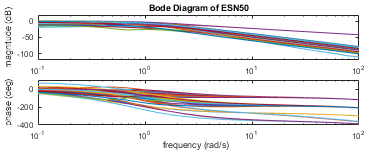

figure('Color',[1 1 1]);
set(gcf,'unit','centimeters','position',figsize);
% set(gca,'Position', figpos);
set(gcf,'Visible','on');
w = logspace(-1,2,30);

ax1 = subplot(2,1,1);
semilogx(w, 20*log10(maglist));
ylabel('magnitude (dB)');
title('Bode Diagram of ESN50');
ylim([-120 20]);
ax2 = subplot(2,1,2);
semilogx(w, phaselist);
xlabel('frequency (rad/s)', Position=[3 -550 0]);
ylabel('phase (deg)');
ylim([-400 100]);

ax1.Position = [0.1 0.6 0.85 0.3];
ax2.Position = [0.1 0.17 0.85 0.3];